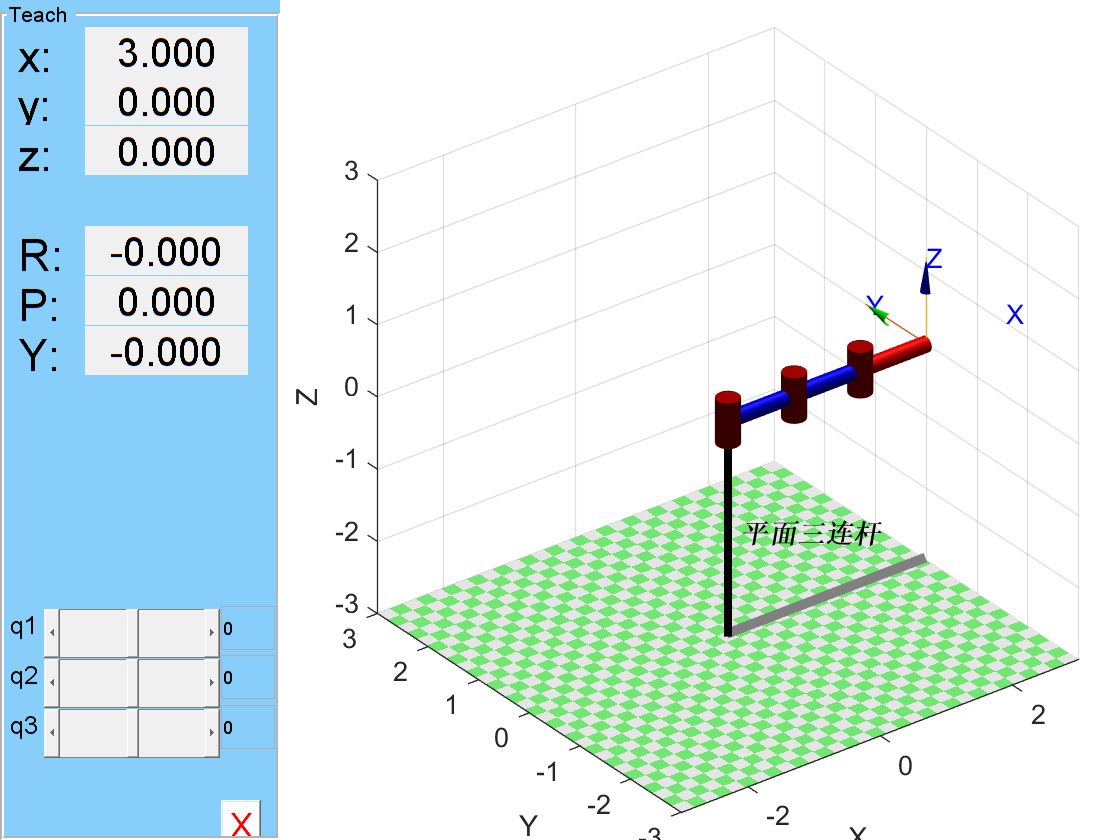

clear;
clc;
import casadi.*

%% 主函数

h = 0.05;  % RK4离散化
Tfinal = 5.0;  % 终止时间
Nt = fix(Tfinal/h)+1;  % 时间步数，即1~N

%% Cost weights

% stage cost l=1/2*(x-x_goal)'*Q(x-x_goal)+1/2*u*R*u
Q = diag([0,0,0,0.00001,0.00001,0.00001,10,10,10]);
R = diag([1,1,1]);
% terminal cost lN=1/2*(x_N-x_goal)'*QN(x_N-x_goal)
QN = diag([0,0,0,70,70,70,2000,2000,1000]);

%% Initial guess

x0 = [0; 0; 0;0;0;0;3;0;0];
xgoal = [0;0;0;0;0;0;0; 2.5; pi/2];
Nx = length(x0);  % 状态变量个数
xtraj = kron(ones(1,Nt), x0);

Nu = 3;  % 输入控制个数
utraj = 0.001*ones(Nu,Nt-1);

%%  DDP
load('planar3link_robot.mat');  % 会恢复变量 robot
robot.teach();  % 继续使用


%if isempty(gcp('nocreate'))
    %parpool(4);  % 只在没有并行池时才开启
%end

%dynamics_jiexi=dynamics(robot,Nu);
%dynamics_rk4_step = rk4_step( h,dynamics_jiexi,Nu);
%dfdx = dfdx(Nx,Nu,dynamics_rk4_step);
%dfdu = dfdu(Nx,Nu,dynamics_rk4_step);
%dAdx = dAdx(Nx,Nu,dfdx);
%dAdu = dAdu(Nx,Nu,dfdx);
%dBdx = dBdx(Nx,Nu,dfdu);
%dBdu = dBdu(Nx,Nu,dfdu);



 for k = 1:(Nt-1)
        xtraj(:,k+1) = rk4_step(xtraj(:,k), utraj(:,k),h,robot);  % 一步RK4
 end

函数或变量 'free' 无法识别。

出错 untitled4>Mq (第 124 行)
disp(free(M));  % 在 Mq 里

出错 untitled4>dynamics (第 75 行)
    M_q = Mq(m,I,DH);

出错 untitled4>rk4_step (第 52 行)
    k1 = dynamics(x, u,robot);

 function x_next  = rk4_step( x,u,h,robot)

    k1 = dynamics(x, u,robot);
    k2 = dynamics(x + 0.5*h*k1, u,robot);
    k3 = dynamics(x + 0.5*h*k2, u,robot);
    k4 = dynamics(x + h*k3, u,robot);

    x_next = x + (h/6)*(k1 + 2*k2 + 2*k3 + k4);
 end

 function dynamics_jiexi = dynamics(x,u,robot)
%% 针对串联机器人
    import casadi.*
    m = [robot.links.m].';  % 连杆质量矩阵
    I = [robot.links.I].';  % 连杆惯性质量矩阵
    for i = 1:3
        link = robot.links(i);
        DH(i, :) = [link.theta, link.d, link.a, link.alpha];
    end  % DH矩阵

    % 定义符号变量
    q = x(1:3);
    qdot = x(4:6);
    DH = MX(DH);
    % 获取动力学参数
    M_q = Mq(m,I,DH);
    M_sym = full(M_q(q));


    C_sym = full(Cqq(q, qdot,M_q));

    G_q = G(robot.gravity,m,DH);
    g_sym = full(G_q(q));
    
    JA = Jacob_geo(q,DH);  % 分析雅可比矩阵
    JA = JA([1,2,6],:);
    %while cond(JA) > 1e12 || isnan(cond(JA))  % 条件数越大表示数值不稳定
        %warning('矩阵 JA 可能是奇异或病态的，跳过这一步或做特殊处理');
        %q=q+[0;0.01;0.02];
        %JA = Jacob_geo(q,DH);  % 分析雅可比矩阵
        %JA = JA([1,2,6],:);
        %double(JA)
    %end

    % 计算各分量
    M_1 = pinv(M_sym, 'symbolicqr');
    qddot = M_1*(u - C_sym*qdot - g_sym);  % 加速度
    end_effectordot = JA * qdot;  % 末端执行器位置变化率

    % 构造 xdot
    xdot = [qdot;
            qddot;
            end_effectordot];

    % 转换为数值函数，方便后续调用
    dynamics_jiexi = Function('dynamics_jiexi', {x, u}, {xdot});
end
function M_func = Mq(m,I,DH)
% 输入：各转动关节角度参数q(n*1)(若n表示关节数量的话)，连杆质量m(n*1)，转动惯量矩阵I(n*1)
% 输出：拉格朗日方程中二阶导项系数矩阵B(q)
    import casadi.*
    q = MX.sym('q',3,1);
    n = length(q);
    M = zeros(n, n);
    J = Jacob_geo(q,DH);
    for i = 1:n
        Ji = MX(zeros(6, n));
        for j = 1:i
            Ji(:, j) = J(:, j);
        end
        M = M+m(i)*Ji(1:3, :)'*Ji(1:3, :)+Ji(4:6, :)'*I(3*i-2:3*i,:)*Ji(4:6, :);
    end
    M_func = Function('M_q',{q},{M});

disp(free(M));  % 在 Mq 里

end
function C = Cqq(q, qdot,M_q)
    import casadi.*
    n = length(q);
    h = 1e-6;
    C = zeros(n, n);


    for i = 1:n
        for j = 1:n
            for k = 1:n
                % 计算∂M_ij/∂q_k
                theta_plus = q;
                theta_plus(k) = theta_plus(k) + h;
                M_plus = M_q(theta_plus);
                
                theta_minus = q;
                theta_minus(k) = theta_minus(k) - h;
                M_minus = M_q(theta_minus);
                
                dM_ij = (M_plus(i,j) - M_minus(i,j))/(2*h);
                
                % 计算∂M_jk/∂q_i
                theta_plus = q;
                theta_plus(i) = theta_plus(i) + h;
                M_plus = M_q(theta_plus);
                
                theta_minus = q;
                theta_minus(i) = theta_minus(i) - h;
                M_minus = M_q(theta_minus);
                
                dM_jk = (M_plus(j,k) - M_minus(j,k))/(2*h);
                
                C(i,j) = C(i,j) + full((dM_ij - 1/2 * dM_jk) )* qdot(k);
            end
        end
    end
end
function G_func = G(g0,m,DH)
% 输入：各转动关节角度参数q(n*1)，连杆质量m(n*1)
% 输出：拉格朗日方程中常数项g(q)
    import casadi.*
    n =3;
    g = MX(zeros(n, 1));

    q = MX.sym('q',3,1);

    J = Jacob_geo(q,DH);
    for i = 1:n
        for j = 1:n
            if ((j-1)>=i)
                g(i) = g(i)-0.5*m(i)*g0'*J(1:3, i);
            end
            if (j>=i)
                g(i) = g(i)-0.5*m(i)*g0'*J(1:3, i);
            end
        end
    end


disp(free(g));  % 在 G 里
    G_func = Function('G_q',{q},{g});
end
